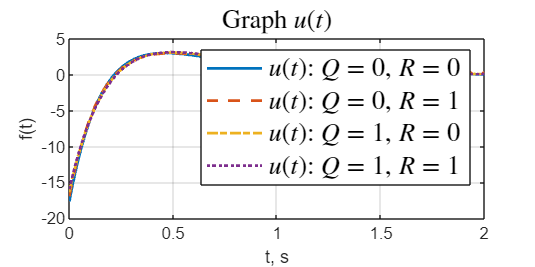

A = [5 8 5; -6 -9 -8; 6 6 5];
B = [2; 0; 0];
x0 = [1; 1; 1];

k_00 = [-6.1063569682151550965343633940624 -6.1063569682151550965343633940624 -5.4095354523227350158165024029618];
k_01 = [-5.9999999999999988296398948743136 -5.9999999999999988296398948743136 -4.9166666666666669974206094195774];
k_10 = [-5.7383341136078177791847209350206 -5.7383341136078177791847209350206 -4.8575011704117287588881690577261];
k_11 = [-5.6107801370529526028060774269925 -5.6107801370529526028060774269925 -4.7418953616298153245817858727135];

K = k_00;
open_system('task_3_sim');
set_param('task_3_sim/x', 'VariableName', 'x')
set_param('task_3_sim/u', 'VariableName', 'u')


out = sim('task_3_sim');

figure('Position', [100 100 800 400])
plot(out.u,'-', 'LineWidth',1.5)
hold on
K = k_01;
out = sim('task_3_sim');
plot(out.u,'--', 'LineWidth',1.5)

K = k_10;
out = sim('task_3_sim');
plot(out.u,'-.', 'LineWidth',1.5)

K = k_11;
out = sim('task_3_sim');
plot(out.u,':', 'LineWidth',1.5)

grid()
title('Graph $u(t)$','Interpreter','latex',  'FontSize', 14)
legend('$u(t)$: $Q = 0$, $R =0$', '$u(t)$: $Q = 0$, $R =1$' ...
    , '$u(t)$: $Q = 1$, $R =0$', '$u(t)$: $Q = 1$, $R =1$', 'Interpreter','latex',  'FontSize', 14)
ylabel('f(t)')
xlabel('t, s')
%xlim([0 5.5])
hold off

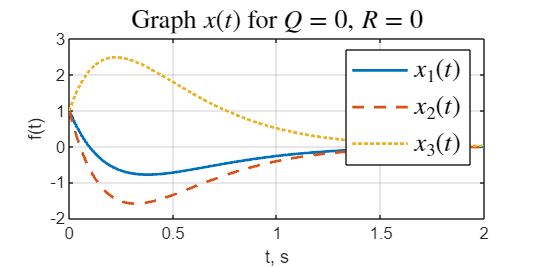



plot(out.x.Time, out.x.Data(:,1),'-', 'LineWidth',1.5)
hold on
plot(out.x.Time, out.x.Data(:,2),'--', 'LineWidth',1.5)
plot(out.x.Time, out.x.Data(:,3),':', 'LineWidth',1.5)

grid()
title('Graph $x(t)$ for $Q = 0$, $R =0$','Interpreter','latex',  'FontSize', 14)
legend('$x_1(t)$', '$x_2(t)$', '$x_3(t)$', 'Interpreter','latex',  'FontSize', 14)
ylabel('f(t)')
xlabel('t, s')
%xlim([0 5.5])
hold off